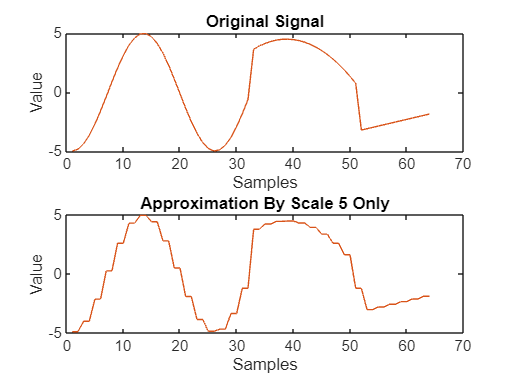

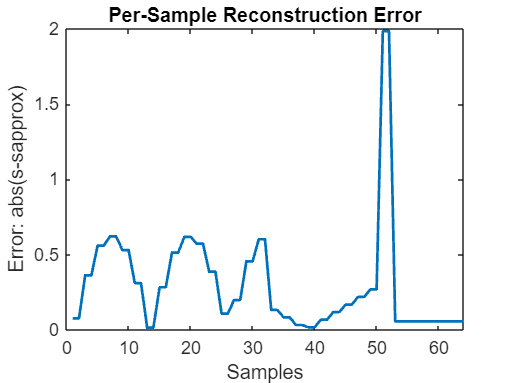

t = linspace(0, 10, 64);
t1 = t(t >=0 & t < 5);
t2 = t(t>=5 & t < 8);
t3 = t(t>=8 & t <= 10);

s1 = -5 .* cos(pi .* t1 ./ 2);
s2 = - (t2 - 6).^2 + 4.5;
s3 = 5 .* t3 ./ 7 - 9;
N = 64;
s = [s1, s2, s3]';
V = nhaar222(N);
% s = V * c
% s/V = c
V = V*diag(1./sqrt(diag(V'*V))) ;
c = V' * s;
% c = s/V;

I = 1;
subplot(2,1,1)
	plot(1:N, s, 'r', 1:N, s)
	title(['Original Signal'])
    xlabel('Samples');
    ylabel('Value');
for k = 1:round(log2(N))
	J = 2^(k-1)+1 : 2^k ;
    I = [I J] ;
	cJ = c.*ismember((1:N)',J) ;
	cI = c.*ismember((1:N)',I) ;
	
 cnew = c .* ismember(1:N, I)';   % N×1 vector with zeros elsewhere
    % Reconstruct approximation
    s_approx = V * cnew;
    e_vec = (norm(s-s_approx)/ norm(s));
    if(e_vec < .15)

        subplot(2,1,2)
	    plot(1:N, s_approx, 'r', 1:N, s_approx)
	    title(['Approximation By Scale 5 Only'])
        xlabel('Samples');
        ylabel('Value');
        figure
        error_vec = abs(s - s_approx);    
        plot(1:N, error_vec, 'LineWidth', 1.5);
        xlabel('Samples');
        ylabel('Error: abs(s-sapprox)');
        title('Per-Sample Reconstruction Error');
        break
    end
end

% Cost
K = 5

K = 5

P = 10 + K^2

P = 35

% $35 per unit would be spent 